
st_meritev = 100;
zacetna_ocena = [2, 2];
tol = 1e-5; % toleranca za konvergenco
bazne_postaje = [1, 1; 10, 5; 2, 4];  % koordinate treh baznih postaj
ponovitve = 100;

% Pridobivanje meritev razdalj do posameznih stolpov
meritve = measurments(st_meritev);    % dobimo 100 meritev

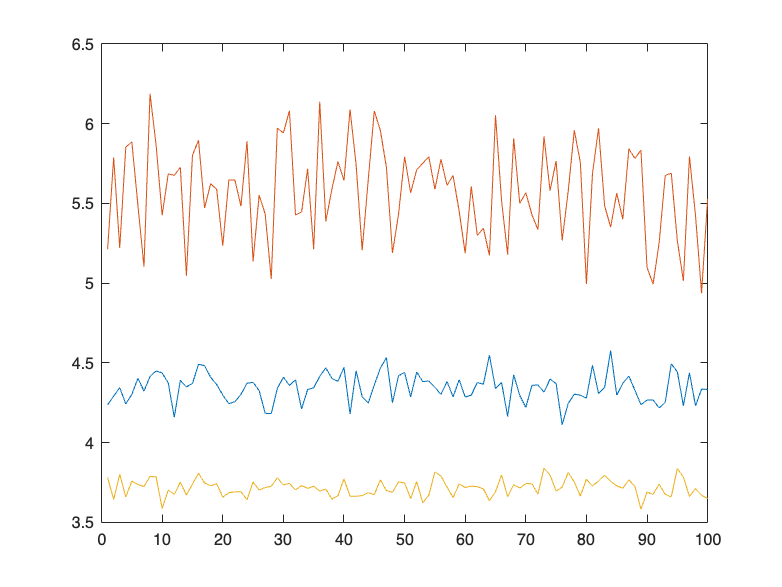

% graf razdalj telefona do posameznega stolpa
% razdalje od posameznega stolpa do telefona
figure;
plot(meritve);

## Izris N meritev posameznih stolpov

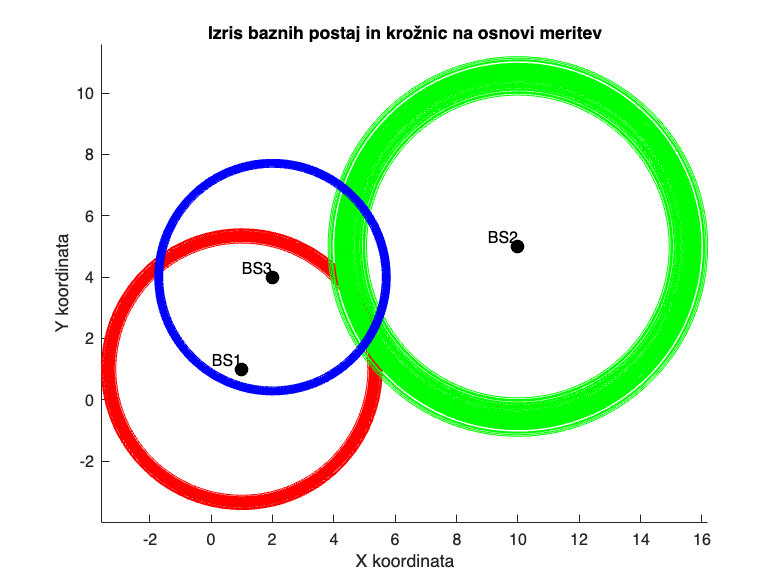


% Definicija barv za posamezne krivulje
colors = ['r', 'g', 'b'];  % rdeča, zelena, modra

% Izris grafa
figure;
hold on;

% Izris baznih postaj
plot(bazne_postaje(:,1), bazne_postaje(:,2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
for i = 1:size(bazne_postaje, 1)
    text(bazne_postaje(i, 1), bazne_postaje(i, 2), sprintf(' BS%d', i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Izris krožnic okoli baznih postaj
theta = linspace(0, 2*pi, 100);  % Parametri za izris krožnice
for i = 1:size(bazne_postaje, 1)
    for j = 1:size(meritve, 1)
        x_circle = bazne_postaje(i, 1) + meritve(j, i) * cos(theta);
        y_circle = bazne_postaje(i, 2) + meritve(j, i) * sin(theta);
        plot(x_circle, y_circle, 'Color', colors(i));
    end
end

% Dodajanje legende in označb

title('Izris baznih postaj in krožnic na osnovi meritev');
xlabel('X koordinata');
ylabel('Y koordinata');
axis equal;  % Za enakomerno razmerje osi

hold off;

## Brez upoštevanja variance

% enakovredne meritve stolpov
utezi = [1, 1, 1];

% inicializiramo matrike za priblizke, variance, st_korakov pa napako
[priblizek, varianca] = deal(zeros(st_meritev, 2));
[st_korakov, napaka] = deal(zeros(st_meritev, 1));

% Optimizacija
for i = 1:st_meritev    % 100x

    % korak optimizacije pozicije
    % vrne oceno pozicije, kovariančno matriko, st iteracij za konergenco,
    % napako
    [pozicija, kovarianca, koraki, error] = levenberg_marquardt(zacetna_ocena, bazne_postaje, meritve(1:i, :), ponovitve, tol, utezi, @Funckija_JF);
    [priblizek(i, :), varianca(i, :), st_korakov(i), napaka(i)] = deal(pozicija, sqrt([kovarianca(1, 1), kovarianca(2, 2)]), koraki, error);
    if i == st_meritev
        variance_stolpov = varianca(i, :);
    end
end


## Prikaz resultatov (brez upoštevanja variance)

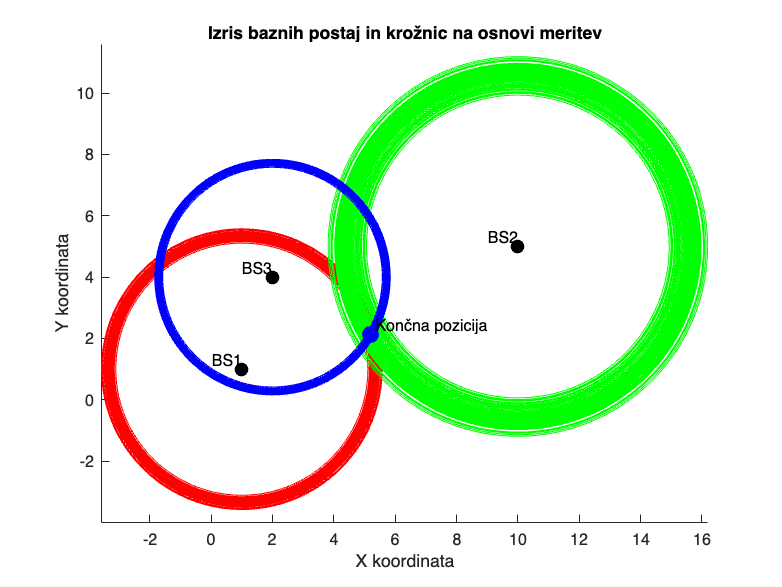


% Definicija barv za posamezne krivulje
colors = ['r', 'g', 'b'];  % rdeča, zelena, modra

% Izris grafa
figure;
hold on;

% Izris baznih postaj
plot(bazne_postaje(:,1), bazne_postaje(:,2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
for i = 1:size(bazne_postaje, 1)
    text(bazne_postaje(i, 1), bazne_postaje(i, 2), sprintf(' BS%d', i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Izris krožnic okoli baznih postaj
theta = linspace(0, 2*pi, 100);  % Parametri za izris krožnice
for i = 1:size(bazne_postaje, 1)
    for j = 1:size(meritve, 1)
        x_circle = bazne_postaje(i, 1) + meritve(j, i) * cos(theta);
        y_circle = bazne_postaje(i, 2) + meritve(j, i) * sin(theta);
        plot(x_circle, y_circle, 'Color', colors(i));
    end
end

% Dodajanje legende in označb
title('Izris baznih postaj in krožnic na osnovi meritev');
xlabel('X koordinata');
ylabel('Y koordinata');
axis equal;  % Za enakomerno razmerje osi

% Prikaz končne pozicije telefona
koncna_pozicija = priblizek(end, :);
plot(koncna_pozicija(1), koncna_pozicija(2), 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 10);
text(koncna_pozicija(1), koncna_pozicija(2), ' Končna pozicija', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');

hold off;

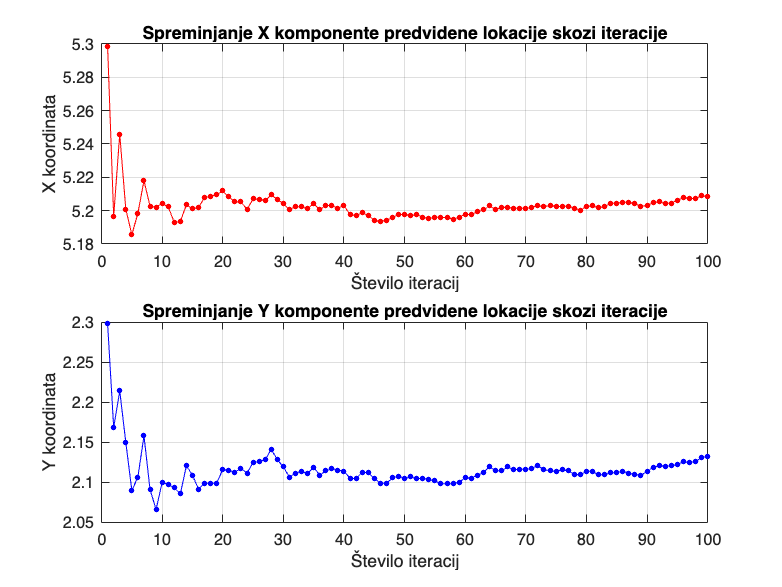



% Izris spreminjanja X komponente predvidene lokacije
figure;
subplot(2, 1, 1);  % Ustvari dve ploskvi v eni figuri, to je prva
plot(1:st_meritev, priblizek(:, 1), 'r.-', 'MarkerSize', 10);
title('Spreminjanje X komponente predvidene lokacije skozi iteracije');
xlabel('Število iteracij');
ylabel('X koordinata');
grid on;

% Izris spreminjanja Y komponente predvidene lokacije
subplot(2, 1, 2);  % Druga ploskev v isti figuri
plot(1:st_meritev, priblizek(:, 2), 'b.-', 'MarkerSize', 10);
title('Spreminjanje Y komponente predvidene lokacije skozi iteracije');
xlabel('Število iteracij');
ylabel('Y koordinata');
grid on;


% Izpis končne lokacije iskanega predmeta
disp('Končna predvidena lokacija iskanega predmeta:');

Končna predvidena lokacija iskanega predmeta:


disp(['X koordinata: ', num2str(koncna_pozicija(1))]);

X koordinata: 5.2085


disp(['Y koordinata: ', num2str(koncna_pozicija(2))]);

Y koordinata: 2.1321



% Izpis števila korakov za konvergenco brez upoštevanja variance
disp('Število korakov za konvergenco (brez upoštevanja variance):');

Število korakov za konvergenco (brez upoštevanja variance):


disp(st_korakov(end));

     6



## Z upoštevanjem variance

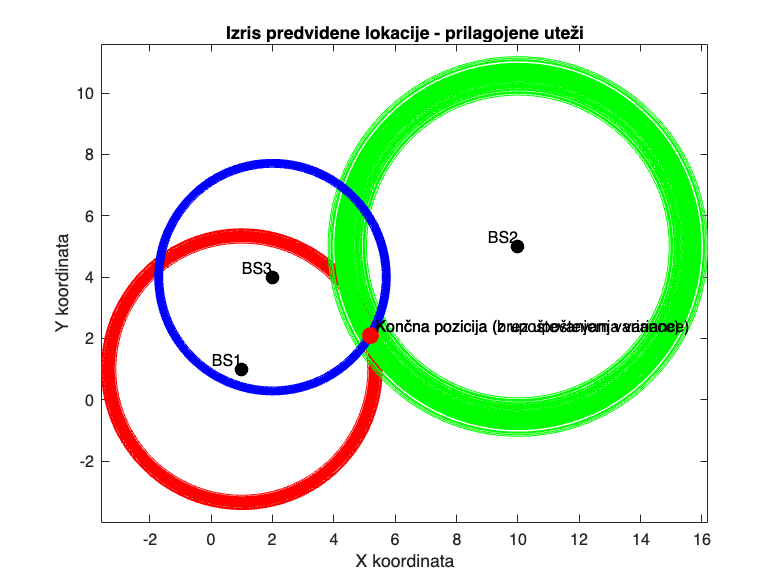

% Izračun uteži na podlagi variance
weights = 1 ./ var(meritve, 0, 1);  

% Inicializacija matrik za rezultate
[priblizek_var, varianca_var] = deal(zeros(st_meritev, 2));
[st_korakov_var, napaka_var] = deal(zeros(st_meritev, 1));

% Optimizacija z upoštevanjem variance
for i = 1:st_meritev
    % Izvedba optimizacije
    [pozicija_var, kovarianca_var, koraki_var, error_var, variances_var] = levenberg_marquardt(zacetna_ocena, bazne_postaje, meritve, ponovitve, tol, weights, @Funckija_JF);
    [priblizek_var(i, :), varianca_var(i, :), st_korakov_var(i), napaka_var(i)] = deal(pozicija_var, sqrt([kovarianca_var(1, 1), kovarianca_var(2, 2)]), koraki_var, error_var);
    
    % Shrani varianco stolpov pri zadnji iteraciji
    if i == st_meritev
        variance_stolpov_var = varianca_var(i, :);
    end
end


figure;
plot(bazne_postaje(:,1), bazne_postaje(:,2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
hold on;
for i = 1:size(bazne_postaje, 1)
    text(bazne_postaje(i, 1), bazne_postaje(i, 2), sprintf(' BS%d', i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Izris krožnic okoli baznih postaj za utežene meritve
theta = linspace(0, 2*pi, 100);  % Parametri za izris krožnice
for i = 1:size(bazne_postaje, 1)
    for j = 1:size(meritve, 1)
        x_circle = bazne_postaje(i, 1) + meritve(j, i) * cos(theta);
        y_circle = bazne_postaje(i, 2) + meritve(j, i) * sin(theta);
        plot(x_circle, y_circle, 'Color', colors(i));
    end
end

plot(priblizek_var(:, 1), priblizek_var(:, 2), 'b--');
plot(priblizek_var(end, 1), priblizek_var(end, 2), 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 10);
text(priblizek_var(end, 1), priblizek_var(end, 2), ' Končna pozicija (brez upoštevanja variance)', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');

plot(priblizek_var(:, 1), priblizek_var(:, 2), 'r--');
plot(priblizek_var(end, 1), priblizek_var(end, 2), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
text(priblizek_var(end, 1), priblizek_var(end, 2), ' Končna pozicija (z upoštevanjem variance)', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');

title('Izris predvidene lokacije - prilagojene uteži');
xlabel('X koordinata');
ylabel('Y koordinata');
axis equal;  
hold off;

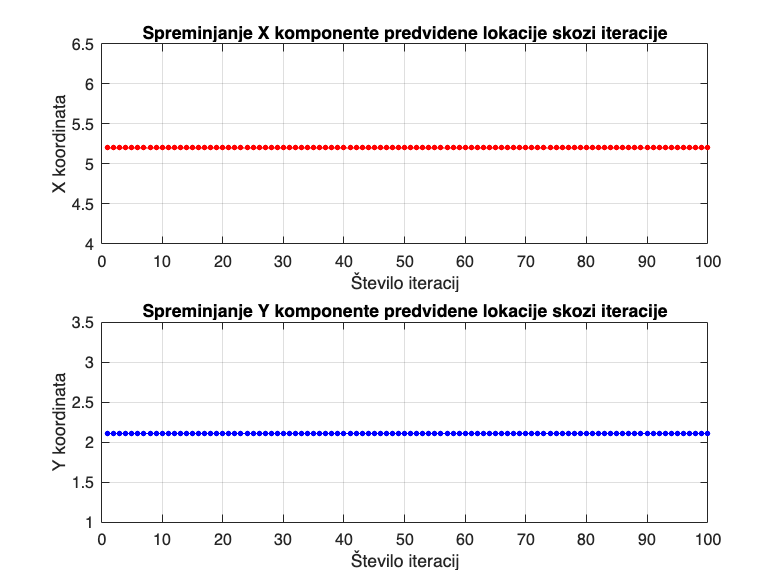


figure;
subplot(2, 1, 1);  % Ustvari dve ploskvi v eni figuri, to je prva
plot(1:st_meritev, priblizek_var(:, 1), 'r.-', 'MarkerSize', 10);
title('Spreminjanje X komponente predvidene lokacije skozi iteracije');
xlabel('Število iteracij');
ylabel('X koordinata');
grid on;

subplot(2, 1, 2);  
plot(1:st_meritev, priblizek_var(:, 2), 'b.-', 'MarkerSize', 10);
title('Spreminjanje Y komponente predvidene lokacije skozi iteracije');
xlabel('Število iteracij');
ylabel('Y koordinata');
grid on;


% Izpis končne lokacije objekta
disp('Končna predvidena lokacija objekta:');

Končna predvidena lokacija objekta:


disp(['X koordinata: ', num2str(priblizek_var(end, 1))]);

X koordinata: 5.1999


disp(['Y koordinata: ', num2str(priblizek_var(end, 2))]);

Y koordinata: 2.1083



% Izpis števila korakov za konvergenco z upoštevanjem variance
disp('Število korakov za konvergenco (z upoštevanjem variance):');

Število korakov za konvergenco (z upoštevanjem variance):


disp(st_korakov_var(end));

     6



function pings = measurments(num_pings)
    pings = [];
    for i = 1:num_pings
        pings = [pings; ping_stolp_1(), ping_stolp_2(), ping_stolp_3()];
    end
end

function [J, f] = Funckija_JF(parametri, w, bazne_postaje, meritve)
    N = size(meritve, 1); % Število meritev
    f = zeros(N * 3, 1); % Inicializacija vektorja funkcije napake
    J = zeros(N * 3, 2); % Inicializacija Jakobijeve matrike

    x = parametri(1);
    y = parametri(2);
    
    for i = 1:N
        for j = 1:size(bazne_postaje, 1)
            % Izračun pričakovane razdalje od trenutnih koordinat do bazne postaje
            d = sqrt((x - bazne_postaje(j, 1))^2 + (y - bazne_postaje(j, 2))^2);
            % Izračun funkcije napake
            f((i-1)*3 + j) = (d - meritve(i, j))*w(j);
            % Izračun Jakobijeve matrike
            J((i-1)*3 + j, 1) = ((x - bazne_postaje(j, 1)) / d)*w(j);
            J((i-1)*3 + j, 2) = ((y - bazne_postaje(j, 2)) / d)*w(j);
        end
    end
end

function [param, delta_param] = update_parameters(param, J, f, alpha)
    % Izračun Hessove matrike
    Hessian = J' * J;

    % Prilagoditev Hessove matrike z alfa
    Hessian_adjusted = Hessian + alpha * eye(length(param));

    % Izračun gradienta
    gradient = J' * f;

    % Reševanje za delta_param (posodobitev parametrov)
    delta_param = -Hessian_adjusted \ gradient;

    % Posodobitev parametrov
    param = param + delta_param';
end

function [param, covariance, steps, err, variances] = levenberg_marquardt(parametri, bazne_postaje, meritve, N, tol, w, Funckija_JF)
    param = parametri;
    alpha = 0.01;
    variances = zeros(N, 2);  % Matrika za shranjevanje variance

    for iter = 1:N
        [J, f] = Funckija_JF(param, w, bazne_postaje, meritve);
        
        % Klic ločene funkcije za izračun in posodobitev
        [param, delta_param] = update_parameters(param, J, f, alpha);

        % Shranjevanje trenutne variance
        Hessian = J' * J;
        cov_matrix = inv(Hessian);  % Kovariančna matrika
        variances(iter, :) = sqrt([cov_matrix(1, 1), cov_matrix(2, 2)]);  % Shranite standardni odklon za x in y

        % Preverjanje konvergence
        if norm(delta_param) < tol
            break;
        end
    end

    % Končni izračuni
    covariance = J' * J;
    steps = iter;
    err = f' * f;
end

